# Classifying cyrillic vowels through hypothesis testing

clc;
close all;
clear variables;

## Creating a datastore for my images

folder_name = fullfile(pwd, 'data', 'raw');
imds = imageDatastore(folder_name, 'LabelSource',"foldernames");
% raw_images = readall(imds);

### Label data 

Get label from filename

imds.Labels = char(imds.Labels); % turn labes to char
N = length(imds.Files);
for i = 1:N
    label = imds.Files{i}(length(folder_name) + 6);
    imds.Labels{i} = label;
end


### Display raw images

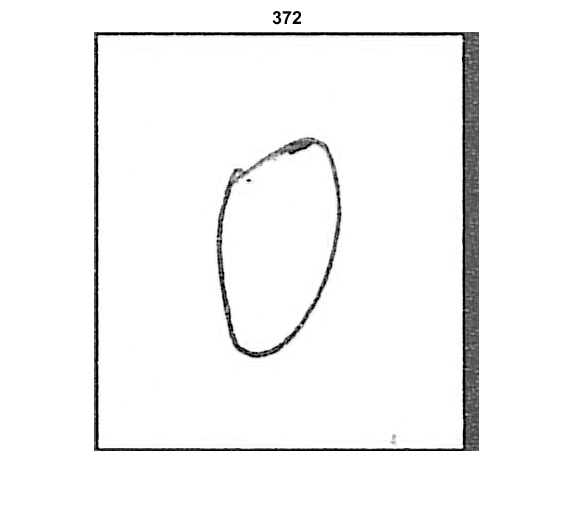

for i=1:1
    figure();
    rand_int = randi(length(imds.Files));
    imshow(readimage(imds, rand_int))
    title(rand_int)
end

## Preprocessing images

bin_threshold = 0.9;
target_size = [400, 400];
final_size = [32, 32];
sigma = 0.5;
medfilt_size = [5, 5];

gauss_flg = false;
median_flg = false;
binarize_before = false;
binarize_after = false;
remove_edges = false;


Images aren't originaly the same size. Following transforms will bug if we don't make them all equal size.

preprocessed_imds = transform(imds, @(x) imresize(x, target_size));

Gaussian blur (maybe unnecessary)

if gauss_flg
    preprocessed_imds = transform(preprocessed_imds, @(x) imgaussfilt(x, sigma));
end

Binarization

if binarize_before
    preprocessed_imds = transform(preprocessed_imds, @(x) binarization(x, bin_threshold));
end

Median blur to fill holes in black and white image (maybe unnecessary)

if median_flg
    preprocessed_imds = transform(preprocessed_imds, @(x) medfilt2(x, medfilt_size));
end

Remove edges

if remove_edges
    preprocessed_imds = transform(preprocessed_imds, @edge_removal);
end

Downsample images for easier computation

preprocessed_imds = transform(preprocessed_imds, @(x) imresize(x, final_size));

if binarize_after
    preprocessed_imds = transform(preprocessed_imds, @(x) binarization(x, bin_threshold));
end

% preprocessed_images = my_readall(preprocessed_imds, N);

### Display preprocessed images

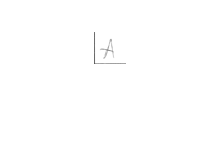

I = preview(preprocessed_imds);
imshow(I)

## Feature extraction

figure('Position', [10 10 900 600]);
imshow(I);
hold on

% hog surf and kaze are good for classification apparently
% https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html

HOG, surf and kaze are good for classification apparently.

[https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html](https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html)

method_name = "hog";
num_points = 10;
cell_size = [10, 10];


Histogram of oriented gradients

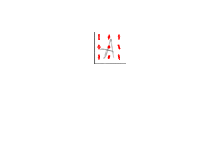

if method_name == "hog"
    [featureVector, visualization] = extractHOGFeatures(I,'CellSize',cell_size);
    plot(visualization, 'Color','red')
end
hold off

### Extract features

if method_name == "hog"
    features_ds = transform(preprocessed_imds, @(x) extractHOGFeatures(x, 'CellSize',cell_size));
end


data = double(readall(features_ds));

### Dimensionality reduction

### Principal component analysis

[coeff,~,~,~,explained,~] = pca(data);

% of info contained in each coordinate

explained

explained =    24.1158
   12.7596
   10.0539
    8.3970
    4.9152
    4.6300
    3.3155
    3.0641
    2.6856
    2.2549


feature_vector_size = 20; % less is more?

% of info contained in the chosen *feature_vector_size* coordinates

sum(explained(1:feature_vector_size))

ans = 87.4333

A_dim_reduction = coeff(:, 1:feature_vector_size);

Data times chosen eigenvectors matrix

features_ds = transform(features_ds, @(x) x * A_dim_reduction);
data_low_dim = double(readall(features_ds));

## Dividing the dataset

split_ratio = 0.7;

all_labels = features_ds.UnderlyingDatastore.Labels;

[training, testing] = divide_dataset(data_low_dim, all_labels, split_ratio, features_ds)

training =   MyDataset with properties:

        labels: {1×420 cell}
          data: [420×20 double]
    file_names: {1×420 cell}


testing =   MyDataset with properties:

        labels: {1×180 cell}
          data: [180×20 double]
    file_names: {1×180 cell}


## Classification

Conduct Bayes' test

training_classes = distribution_parameters(training);
test_result = cell(length(testing.labels), 1);

for i = 1:length(testing.labels)
   test_result{i} = char(bayes_test_least_error(testing.data(i, :), training_classes));
end

Calculate and plot confusion matrix

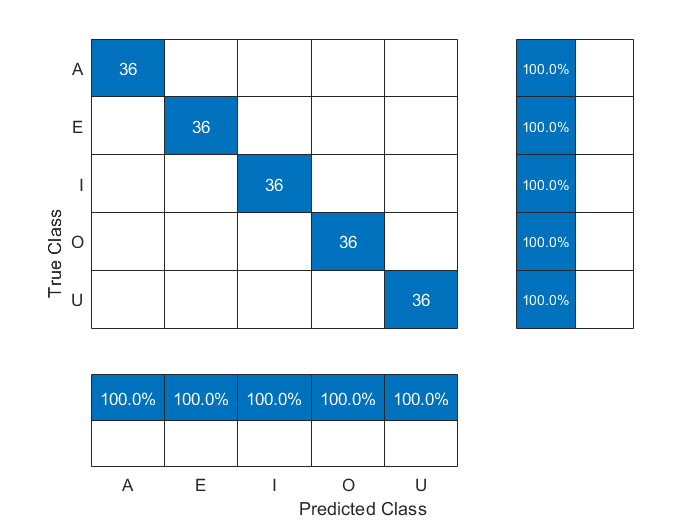

conf_mat = confusionmat(testing.labels, test_result);

% TODO videti da l moze true class da bude po X osi a Predicted po Y
figure()
cm = confusionchart(conf_mat, unique(all_labels), "ColumnSummary","column-normalized", 'RowSummary',"row-normalized");

% TODO - uraditi evaluaciju klasifikatora (npr. K-fold)
incorrect_indices = find([testing.labels{:}] ~= [test_result{:}]);
incorrectly_classified_files = testing.file_names(incorrect_indices)'


incorrectly_classified_files =

  0×1 empty cell array




for i = 1:length(incorrectly_classified_files)
    figure();
    set(gcf,'Visible','on')
    I = imread(incorrectly_classified_files{i});
    imshow(I)
    title("True = " + testing.labels{incorrect_indices(i)} + " Predicted = " + test_result{incorrect_indices(i)})
end